# Polynomial Regression

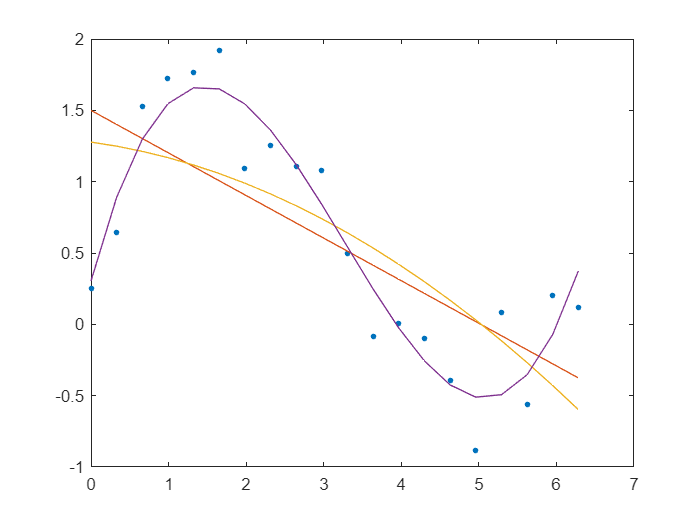

clear;clc;

n = 20;
t = linspace(0,2*pi,n)';
Y = sin(t)+rand(size(t));
plot(t,Y,'.', "MarkerSize",10);
hold on;
for d = 1:3
    X = t.^(0:d);    
    Wsol = ((X'*X)\X')*Y;
    Ypred = X*Wsol;    
    plot(t,Ypred);
end